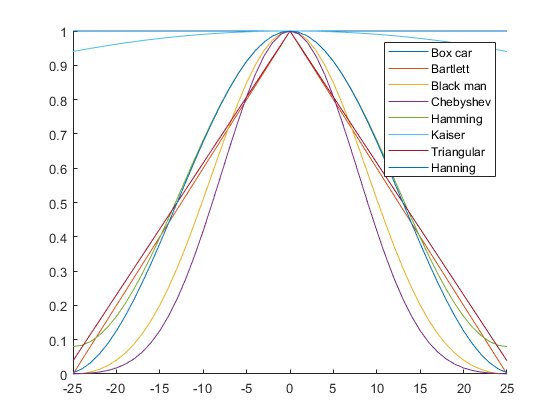

t = 50;
time = (-t/2):(t/2); 

h = 0.5*sinc((0.5*time)/pi);

% --- okna -------------------------
figure(1);
hold on;
Legend{1} = "Box car";
plot(time,boxcar(length(h)));
Legend{2} = "Bartlett";
plot(time,bartlett(length(h)));
Legend{3} = "Black man";
plot(time,blackman(length(h)));
Legend{4} = "Chebyshev";
plot(time,chebwin(length(h)));
Legend{5} = "Hamming";
plot(time,hamming(length(h)));
Legend{6} = "Kaiser";
plot(time,kaiser(length(h)));
Legend{7} = "Triangular";
plot(time,triang(length(h)));
Legend{8} = "Hanning";
plot(time,hanning(length(h)));

legend(Legend,'Location','northeast');

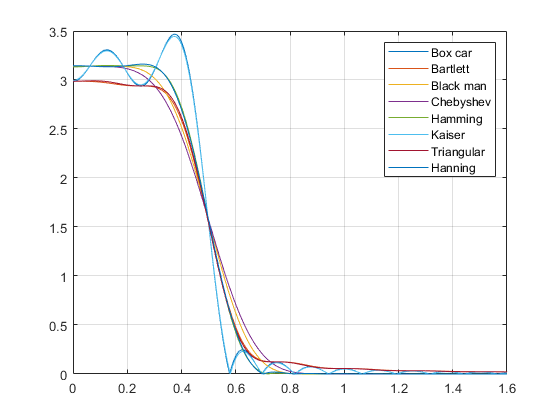


% --- Obdelnik ----------------------
figure(2);
h = 0.5*sinc((0.5*time)/pi);
h = (boxcar(length(h))).*h';
[H,omega] = freqz(h,1,2048);
Legend{1} = "Box car";
plot(omega,abs(H));
hold on;
% --- Bartlett ----------------------
h = 0.5*sinc((0.5*time)/pi);
h = (bartlett(length(h))).*h';
[H,omega] = freqz(h',1,2048); % 2048 větší hustota měření (implicitně 512)
Legend{2} = "Bartlett";
plot(omega,abs(H));
hold on;
% --- Black Man ----------------------
h = 0.5*sinc((0.5*time)/pi);
h = (blackman(length(h))).*h';
[H,omega] = freqz(h',1,2048); 
plot(omega,abs(H));
hold on;
% --- Chebyshev ----------------------
h = 0.5*sinc((0.5*time)/pi);
h = (chebwin(length(h))).*h';
[H,omega] = freqz(h',1,2048); 
plot(omega,abs(H));
hold on;
% --- Hamming ----------------------
h = 0.5*sinc((0.5*time)/pi);
h = (hamming(length(h))).*h';
[H,omega] = freqz(h',1,2048); 
plot(omega,abs(H));
hold on;
% --- Kaiser ----------------------
h = 0.5*sinc((0.5*time)/pi);
h = (kaiser(length(h))).*h';
[H,omega] = freqz(h',1,2048); 
plot(omega,abs(H));
hold on;
% --- Triangular ------------------
h = 0.5*sinc((0.5*time)/pi);
h = (triang(length(h))).*h';
[H,omega] = freqz(h',1,2048); 
plot(omega,abs(H));
hold on;
% --- Hanning ------------------
h = 0.5*sinc((0.5*time)/pi);
h = (hanning(length(h))).*h';
[H,omega] = freqz(h',1,2048); 
plot(omega,abs(H));
hold on;

legend(Legend,'Location','northeast');
xlim([0,1.6]);
grid on;